% main function file for SVM classification of hand digit data
% Lucky Yerimah
% load data
%cd 'C:\Users\lucky\Desktop\Matlab\Machine learning\SVM'
clear all
close all
clc
%
[trainset,testset] = getdata();
%load besttrainset


type = 'poly';
C = 0.15;%linspace(0.0001,1,100);
ytrue = trainset(:,end);
order = 8; % order of polynomial kernel
%gamma = 100; order = gamma; % gamma if type is rbf
for i = 1:length(C)
    svmm = svmclassifier(trainset(:,1:2),trainset(:,end),C(i),type,order);
    yhat = svmprediction(svmm,trainset(:,1:2),type,order);
    missed = find(ytrue ~= yhat);
    Error(i) = length(missed)/length(yhat);
    Error(i)
end

ans = 0.0367

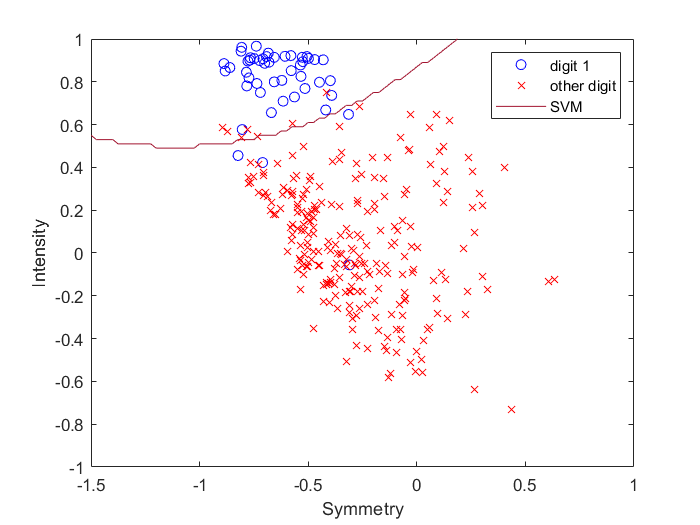


j0 = find(trainset(:,3) ~= 1);
j1 = find(trainset(:,3) == 1);
x1 = linspace(-1.5,1,101); x2 = linspace(-1,1,101);
[X1,X2] = meshgrid(x1,x2);
XX1 = reshape(X1,[],1); XX2 = reshape(X2,[],1);
Z = svmprediction(svmm,[XX1,XX2],type,order);
Z = reshape(Z,length(X1),[]);

close all
figure
plot(trainset(j1,1),trainset(j1,2),'bo')
hold on
plot(trainset(j0,1),trainset(j0,2),'rx')
contour(X1,X2,Z,1,'Color',	'#A2142F')

ylabel('Intensity')
xlabel('Symmetry')

legend('digit 1','other digit','SVM')

ytrue = testset(:,end);
yhat = svmprediction(svmm,testset(:,1:2),type,order);
    missed = find(ytrue ~= yhat);
    Error = length(missed)/length(yhat)

Error = 0.0165